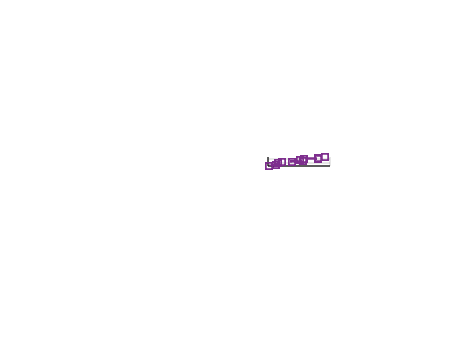

% Example MATLAB code to fit 3D points to linear for x, y and parabolic for z
% with data provided as a list of tuples (x, y, z)

% Input data: list of tuples (x, y, z)
data = [ % Replace this with your data
    1, 2, 3;
    2, 4, 8;
    3, 6, 15;
    4, 8, 24;
    5, 10, 35;
    6, 12, 48;
    7, 14, 63
];

% Extract x, y, and z from the data
x = data(:, 1); % X coordinates (linear)
y = data(:, 2); % Y coordinates (linear)
z = data(:, 3); % Z coordinates (parabolic)

% Define t as the index of each point
t = (1:size(data, 1))'; % Time points (1, 2, 3, ...)

% Center and scale the time data
t_mean = mean(t);      % Calculate the mean of t
t_scaled = t - t_mean; % Center the t values (subtract mean)

% Fit x(t) to a linear model (degree 1 polynomial)
p_x = polyfit(t_scaled, x, 1); % p_x = [a_x, b_x]
x_fit = polyval(p_x, t_scaled); % Fitted x coordinates

% Fit y(t) to a linear model (degree 1 polynomial)
p_y = polyfit(t_scaled, y, 1); % p_y = [a_y, b_y]
y_fit = polyval(p_y, t_scaled); % Fitted y coordinates

% Fit z(t) to a quadratic (parabolic) model (degree 2 polynomial)
p_z = polyfit(t_scaled, z, 2); % p_z = [a_z, b_z, c_z]
z_fit = polyval(p_z, t_scaled); % Fitted z coordinates

% Plot the original points and the fitted curves
figure;

% Plot x(t) vs t
subplot(3, 1, 1);
plot(t, x, 'o', t, x_fit, '-');
xlabel('Time (t)');
ylabel('X Coordinate');
title('Linear Fit for X(t)');
legend('Original Points', 'Fitted Line');

% Plot y(t) vs t
subplot(3, 1, 2);
plot(t, y, 'o', t, y_fit, '-');
xlabel('Time (t)');
ylabel('Y Coordinate');
title('Linear Fit for Y(t)');
legend('Original Points', 'Fitted Line');

% Plot z(t) vs t
subplot(3, 1, 3);
plot(t, z, 'o', t, z_fit, '-');
xlabel('Time (t)');
ylabel('Z Coordinate');
title('Parabolic Fit for Z(t)');
legend('Original Points', 'Fitted Curve');


% Display the polynomial coefficients
disp('Fitted coefficients for X(t):');

Fitted coefficients for X(t):


disp(p_x);

    1.0000    4.0000



disp('Fitted coefficients for Y(t):');

Fitted coefficients for Y(t):


disp(p_y);

    2.0000    8.0000



disp('Fitted coefficients for Z(t):');

Fitted coefficients for Z(t):


disp(p_z);

    1.0000   10.0000   24.0000

